load_sl_glibc_patch;
ele=importrobot('/home/mkris/catkin_ws/src/testbot_description/urdf/ele.urdf');
ltd=3.122;
inverseKinematicsDesigner('ik_one_leg.mat')

load("ik_one_leg.mat")
leg = ikSolver.RigidBodyTree;
a=trvec2tform([-0.7474,1.4820,-10.4356]);
b=axang2tform([0 0 1 -1.39626])

b =     0.1737    0.9848         0         0
   -0.9848    0.1737         0         0
         0         0    1.0000         0
         0         0         0    1.0000


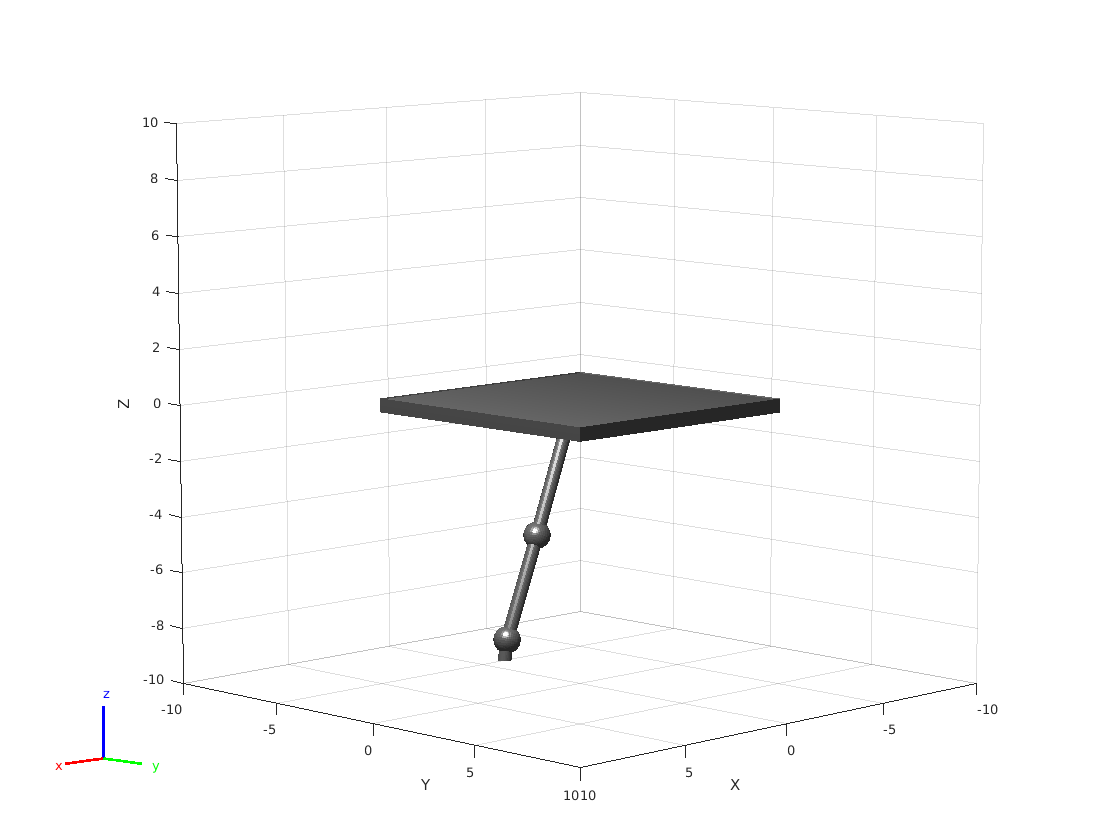

ikConstraints{1}.TargetTransform = a*b;
[qSol, info] = ikSolver(leg.homeConfiguration, ikConstraints{:});
show(leg, qSol);